clearvars
global  net options mm co MaxEpochs ...
        trainImages valImages testImages ...
        trainLabels valLabels testLabels ...
        imageAugmenter trainDS valDS testDS 

Load training data

loadtrainingdata

Define search space for Bayesian optimization

optimVars = [
    optimizableVariable('lr',[0.15,0.25])
    optimizableVariable('mb',[150,350],'Type','integer')
    optimizableVariable('dr',[10,40],'Type','integer')
    optimizableVariable('mo',[0.8,0.99])
    optimizableVariable('lrdf',[0.1,0.9])
    optimizableVariable('l2',[1e-6,1e-2],'Transform','log')
    optimizableVariable('vp',[5,50],'Type','integer')
];
mm = 'sgdm';
co = 5;
MaxEpochs = 100;
numitr = 30;

seeding

initialPoint = table(0.2, 256, 30, 0.9, 0.1, 0.001, 25, ...
    'VariableNames', {'lr','mb','dr','mo','lrdf','l2','vp'});

Objective function

objFcn = @(x)trainAndValidate(x);

Run Bayesian optimization

ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.2000
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 30
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 156
              ValidationPatience: 25
             ObjectiveMetricName:


=== Running Training 1 ===



=== Done Training 1 ===


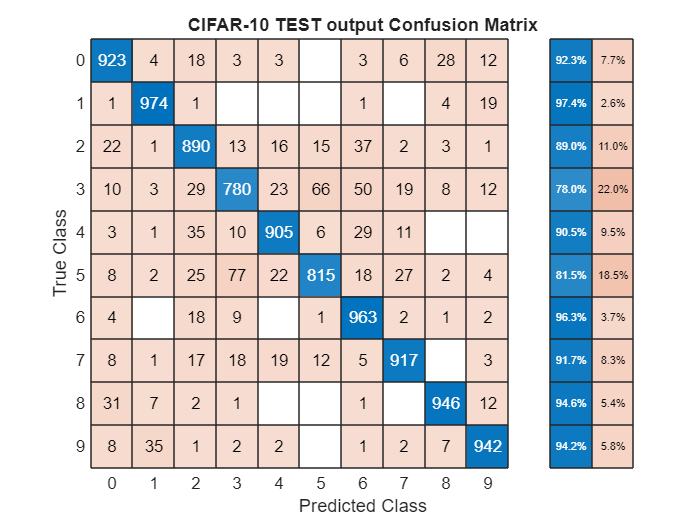

Overall Accuracy (from CM): 90.55%


trainAcc = 0.9904

valAcc = 0.9169

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |           lr |           mb |           dr |           mo |         lrdf |           l2 |           vp |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |     0.11985 |      2283.1 |     0.11985 |     0.11985 |          0.2 |          256 |           30 |          0.9 |          0.1 |        0.001 |           25 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8191
                InitialLearnRate: 0.1588
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.7894
             LearnRateDropPeriod: 37
                   MiniBatchSize: 293
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.6010e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 136
              ValidationPatience: 48
             ObjectiveMetricName:


=== Running Training 2 ===



=== Done Training 2 ===


Overall Accuracy (from CM): 89.2%


trainAcc = 0.9831

valAcc = 0.8928

|    2 | Accept |     0.15237 |      2443.6 |     0.11985 |      0.1216 |       0.1588 |          293 |           37 |       0.8191 |       0.7894 |    0.0001601 |           48 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8571
                InitialLearnRate: 0.2256
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.3596
             LearnRateDropPeriod: 35
                   MiniBatchSize: 280
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0076e-05
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 142
              ValidationPatience: 41
             ObjectiveMetricName:


=== Running Training 3 ===



=== Done Training 3 ===


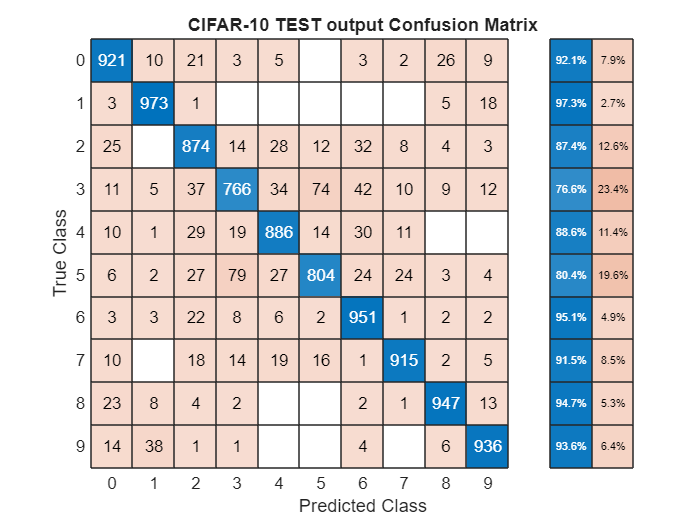

Overall Accuracy (from CM): 89.73%


trainAcc = 0.9957

valAcc = 0.9070

|    3 | Accept |     0.13732 |      1883.7 |     0.11985 |     0.12109 |      0.22555 |          280 |           35 |      0.85714 |      0.35965 |   1.0076e-05 |           41 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9474
                InitialLearnRate: 0.1901
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.8559
             LearnRateDropPeriod: 30
                   MiniBatchSize: 257
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 7.4942e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 155
              ValidationPatience: 41
             ObjectiveMetricName:


=== Running Training 4 ===



=== Done Training 4 ===


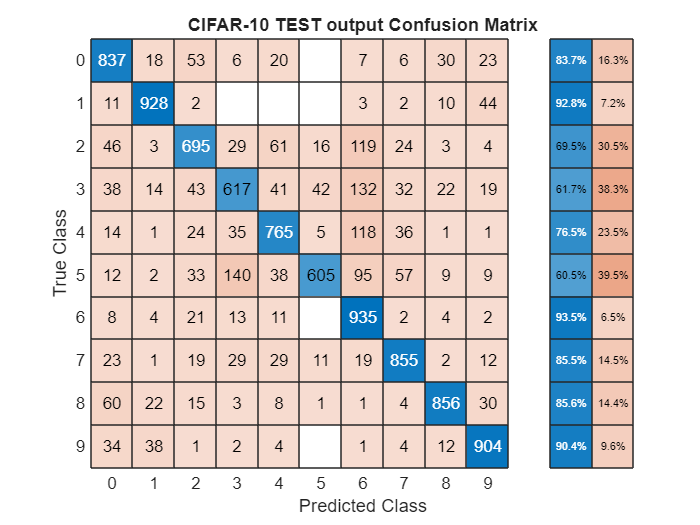

Overall Accuracy (from CM): 79.97%


trainAcc = 0.8245

valAcc = 0.8038

|    4 | Accept |     0.20655 |      2477.6 |     0.11985 |     0.11986 |      0.19011 |          257 |           30 |       0.9474 |      0.85587 |   0.00074942 |           41 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8482
                InitialLearnRate: 0.1532
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1020
             LearnRateDropPeriod: 13
                   MiniBatchSize: 261
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0016
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 153
              ValidationPatience: 9
             ObjectiveMetricName: 'los


=== Running Training 5 ===



=== Done Training 5 ===


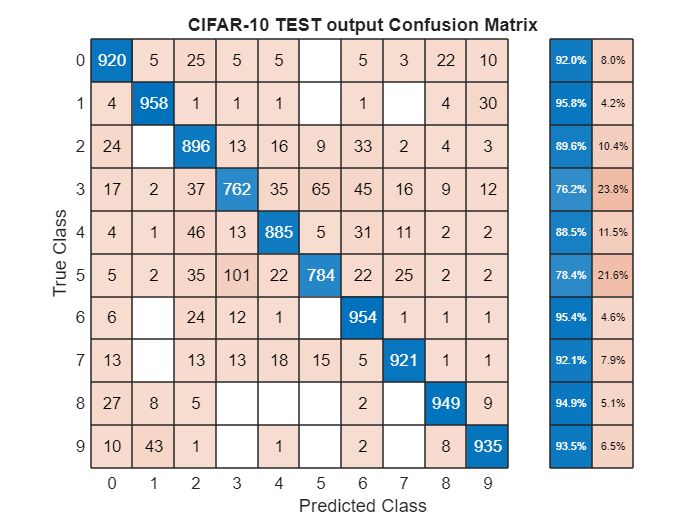

Overall Accuracy (from CM): 89.64%


trainAcc = 0.9672

valAcc = 0.9056

|    5 | Accept |     0.12519 |      1254.1 |     0.11985 |     0.11986 |      0.15318 |          261 |           13 |      0.84824 |      0.10204 |    0.0016135 |            9 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9891
                InitialLearnRate: 0.2251
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1013
             LearnRateDropPeriod: 13
                   MiniBatchSize: 347
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0078
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 115
              ValidationPatience: 19
             ObjectiveMetricName: 'lo


=== Running Training 6 ===



=== Done Training 6 ===


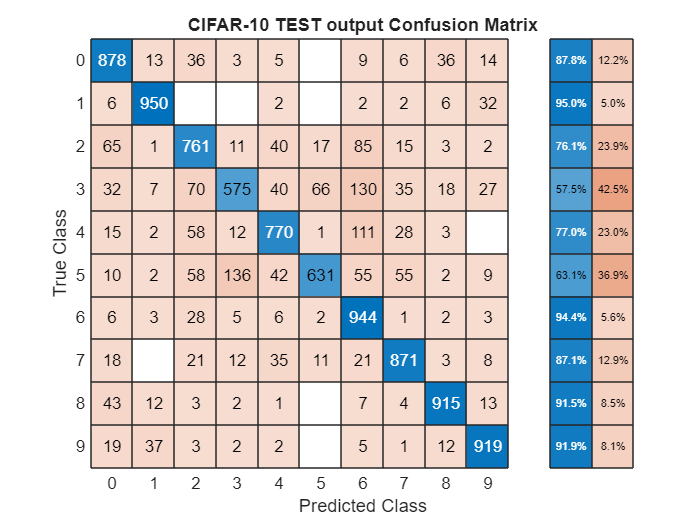

Overall Accuracy (from CM): 82.14%


trainAcc = 0.8650

valAcc = 0.8278

|    6 | Accept |     0.19081 |      2538.7 |     0.11985 |     0.11987 |      0.22508 |          347 |           13 |      0.98914 |      0.10127 |    0.0078248 |           19 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9288
                InitialLearnRate: 0.1948
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2030
             LearnRateDropPeriod: 13
                   MiniBatchSize: 244
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.7219e-05
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 163
              ValidationPatience: 30
             ObjectiveMetricName:


=== Running Training 7 ===



=== Done Training 7 ===


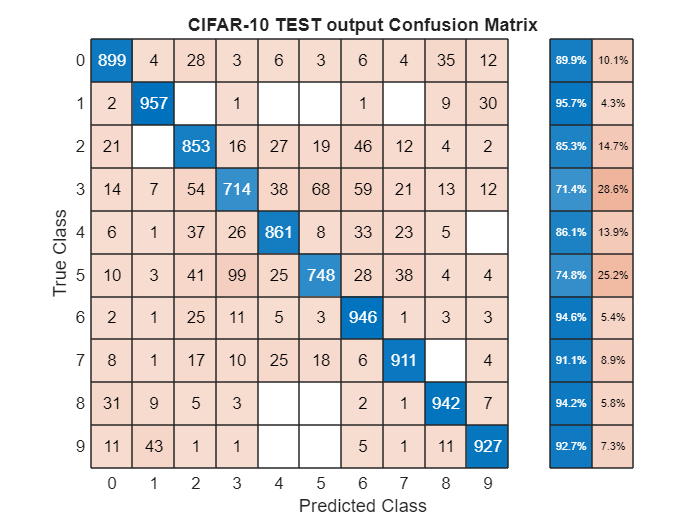

Overall Accuracy (from CM): 87.58%


trainAcc = 0.9579

valAcc = 0.8825

|    7 | Accept |     0.15519 |      1543.6 |     0.11985 |     0.11987 |      0.19479 |          244 |           13 |      0.92881 |        0.203 |   1.7219e-05 |           30 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8801
                InitialLearnRate: 0.1906
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1041
             LearnRateDropPeriod: 30
                   MiniBatchSize: 257
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0033
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 155
              ValidationPatience: 29
             ObjectiveMetricName: 'lo


=== Running Training 8 ===



=== Done Training 8 ===


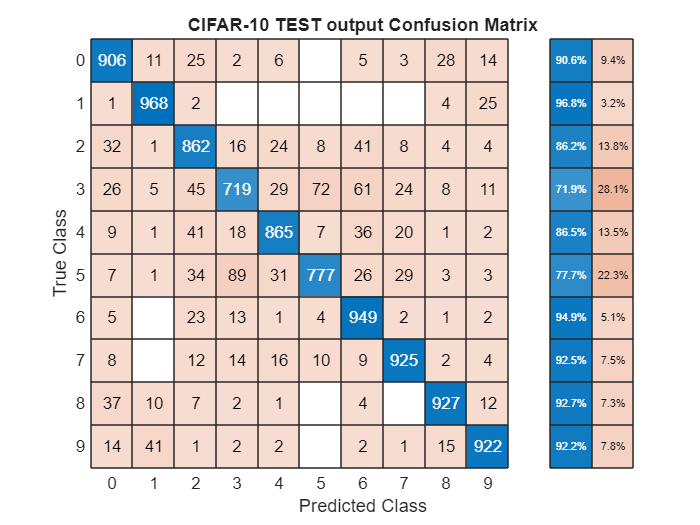

Overall Accuracy (from CM): 88.2%


trainAcc = 0.9527

valAcc = 0.8938

|    8 | Accept |     0.13567 |      2563.3 |     0.11985 |     0.12911 |      0.19059 |          257 |           30 |      0.88013 |      0.10411 |       0.0033 |           29 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9609
                InitialLearnRate: 0.2118
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1082
             LearnRateDropPeriod: 18
                   MiniBatchSize: 273
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 7.2988e-05
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 146
              ValidationPatience: 43
             ObjectiveMetricName:


=== Running Training 9 ===



=== Done Training 9 ===


Overall Accuracy (from CM): 88.95%


trainAcc = 0.9688

valAcc = 0.8980

|    9 | Accept |     0.13741 |        2228 |     0.11985 |     0.11986 |      0.21176 |          273 |           18 |      0.96086 |      0.10822 |   7.2988e-05 |           43 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9037
                InitialLearnRate: 0.1679
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2133
             LearnRateDropPeriod: 38
                   MiniBatchSize: 259
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 3.6540e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 154
              ValidationPatience: 21
             ObjectiveMetricName:


=== Running Training 10 ===



=== Done Training 10 ===


Overall Accuracy (from CM): 89.1%


trainAcc = 0.9657

valAcc = 0.8895

|   10 | Accept |     0.14863 |      1630.2 |     0.11985 |      0.1252 |      0.16793 |          259 |           38 |      0.90375 |      0.21329 |    0.0003654 |           21 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8304
                InitialLearnRate: 0.1832
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1001
             LearnRateDropPeriod: 26
                   MiniBatchSize: 228
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0014
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 175
              ValidationPatience: 46
             ObjectiveMetricName: 'lo


=== Running Training 11 ===



=== Done Training 11 ===


Overall Accuracy (from CM): 91.07%


trainAcc = 0.9930

valAcc = 0.9177

|   11 | Accept |     0.11996 |      2609.7 |     0.11985 |     0.11984 |      0.18319 |          228 |           26 |      0.83036 |      0.10005 |    0.0014255 |           46 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9642
                InitialLearnRate: 0.1750
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1107
             LearnRateDropPeriod: 31
                   MiniBatchSize: 224
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 4.5080e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 178
              ValidationPatience: 49
             ObjectiveMetricName:


=== Running Training 12 ===



=== Done Training 12 ===


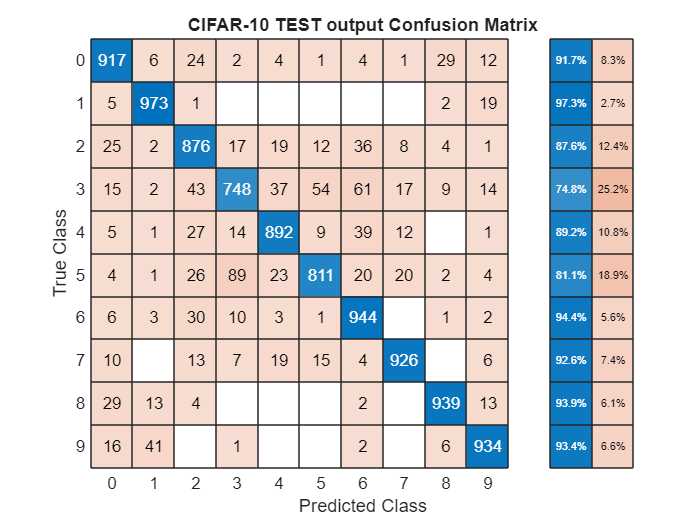

Overall Accuracy (from CM): 89.6%


trainAcc = 0.9789

valAcc = 0.9037

|   12 | Accept |     0.13391 |      2629.4 |     0.11985 |     0.11984 |      0.17496 |          224 |           31 |      0.96419 |      0.11075 |    0.0004508 |           49 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9764
                InitialLearnRate: 0.2008
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1012
             LearnRateDropPeriod: 28
                   MiniBatchSize: 156
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 6.7594e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 256
              ValidationPatience: 5
             ObjectiveMetricName: 


=== Running Training 13 ===



=== Done Training 13 ===


Overall Accuracy (from CM): 52.88%


trainAcc = 0.5432

valAcc = 0.5388

|   13 | Accept |     0.46339 |      351.61 |     0.11985 |     0.12325 |      0.20077 |          156 |           28 |      0.97639 |      0.10116 |   0.00067594 |            5 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8428
                InitialLearnRate: 0.1611
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1195
             LearnRateDropPeriod: 28
                   MiniBatchSize: 302
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0011
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 132
              ValidationPatience: 47
             ObjectiveMetricName: 'lo


=== Running Training 14 ===



=== Done Training 14 ===


Overall Accuracy (from CM): 91.38%


trainAcc = 0.9966

valAcc = 0.9158

|   14 | Accept |     0.12458 |      2513.9 |     0.11985 |       0.123 |      0.16109 |          302 |           28 |      0.84283 |      0.11953 |    0.0011206 |           47 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8041
                InitialLearnRate: 0.2032
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1390
             LearnRateDropPeriod: 13
                   MiniBatchSize: 284
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0054
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 140
              ValidationPatience: 35
             ObjectiveMetricName: 'lo


=== Running Training 15 ===



=== Done Training 15 ===


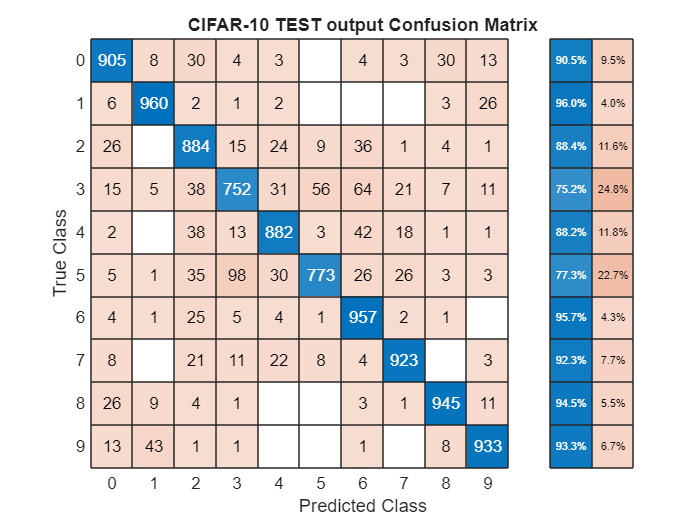

Overall Accuracy (from CM): 89.14%


trainAcc = 0.9584

valAcc = 0.9019

|   15 | Accept |     0.12634 |      2789.8 |     0.11985 |     0.12389 |      0.20319 |          284 |           13 |      0.80408 |      0.13902 |    0.0053922 |           35 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8151
                InitialLearnRate: 0.1568
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1035
             LearnRateDropPeriod: 11
                   MiniBatchSize: 293
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.2674e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 136
              ValidationPatience: 29
             ObjectiveMetricName:


=== Running Training 16 ===



=== Done Training 16 ===


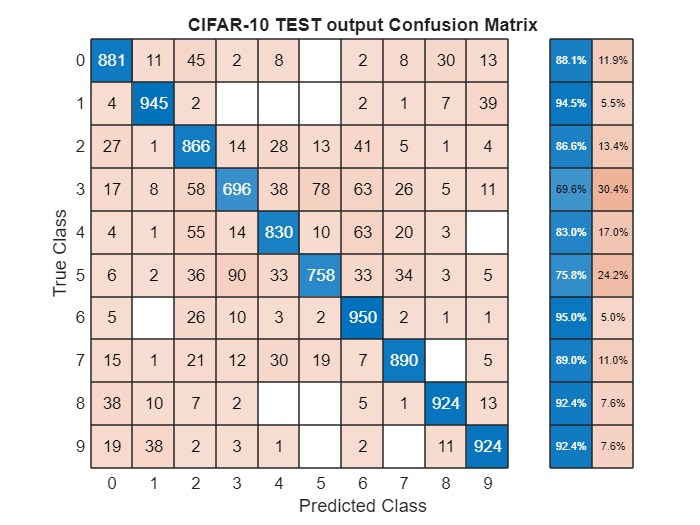

Overall Accuracy (from CM): 86.64%


trainAcc = 0.9197

valAcc = 0.8697

|   16 | Accept |      0.1553 |      2345.2 |     0.11985 |     0.12958 |      0.15682 |          293 |           11 |      0.81513 |      0.10355 |   0.00012674 |           29 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8281
                InitialLearnRate: 0.2064
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.8962
             LearnRateDropPeriod: 36
                   MiniBatchSize: 326
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0081
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 122
              ValidationPatience: 48
             ObjectiveMetricName: 'lo


=== Running Training 17 ===



=== Done Training 17 ===


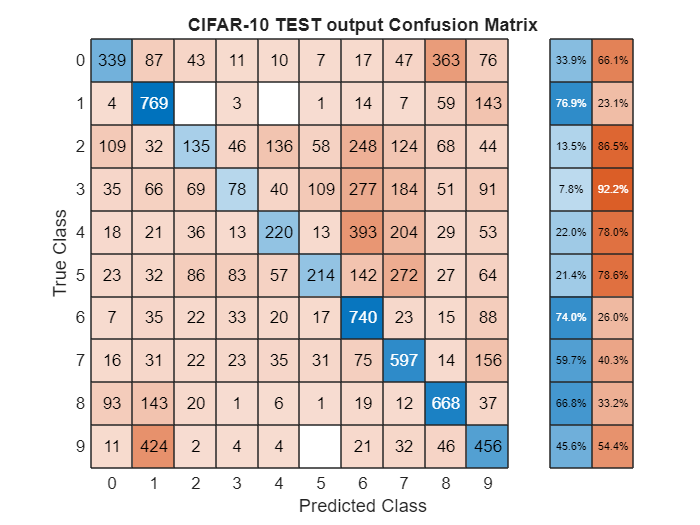

Overall Accuracy (from CM): 42.16%


trainAcc = 0.4361

valAcc = 0.4283

|   17 | Accept |     0.57559 |      1522.4 |     0.11985 |     0.12478 |      0.20641 |          326 |           36 |      0.82812 |      0.89622 |    0.0080598 |           48 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9784
                InitialLearnRate: 0.2435
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.6524
             LearnRateDropPeriod: 32
                   MiniBatchSize: 255
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.4196e-06
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 156
              ValidationPatience: 19
             ObjectiveMetricName:


=== Running Training 18 ===



=== Done Training 18 ===


Overall Accuracy (from CM): 87.6%


trainAcc = 0.9608

valAcc = 0.8862

|   18 | Accept |     0.15109 |      1587.2 |     0.11985 |     0.12463 |      0.24352 |          255 |           32 |      0.97838 |      0.65236 |   1.4196e-06 |           19 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9083
                InitialLearnRate: 0.1690
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2717
             LearnRateDropPeriod: 38
                   MiniBatchSize: 337
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.8197e-06
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 118
              ValidationPatience: 40
             ObjectiveMetricName:


=== Running Training 19 ===



=== Done Training 19 ===


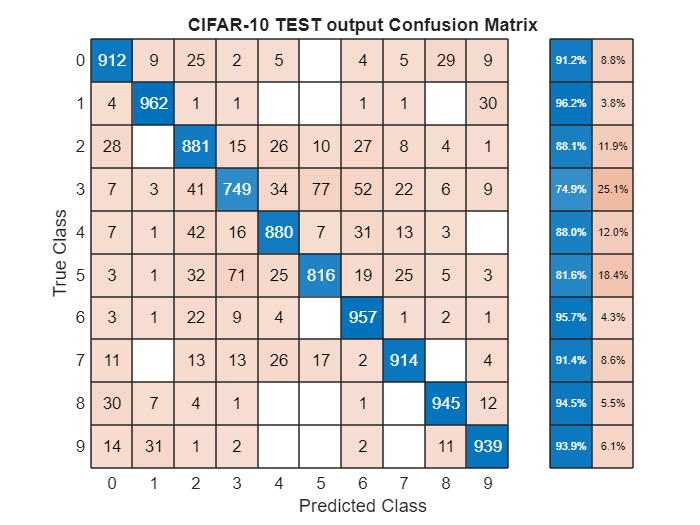

Overall Accuracy (from CM): 89.55%


trainAcc = 0.9954

valAcc = 0.9003

|   19 | Accept |     0.14726 |      2163.6 |     0.11985 |     0.12196 |      0.16899 |          337 |           38 |      0.90828 |      0.27174 |   1.8197e-06 |           40 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8598
                InitialLearnRate: 0.1989
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.6384
             LearnRateDropPeriod: 12
                   MiniBatchSize: 286
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 9.9032e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 139
              ValidationPatience: 40
             ObjectiveMetricName:


=== Running Training 20 ===



=== Done Training 20 ===


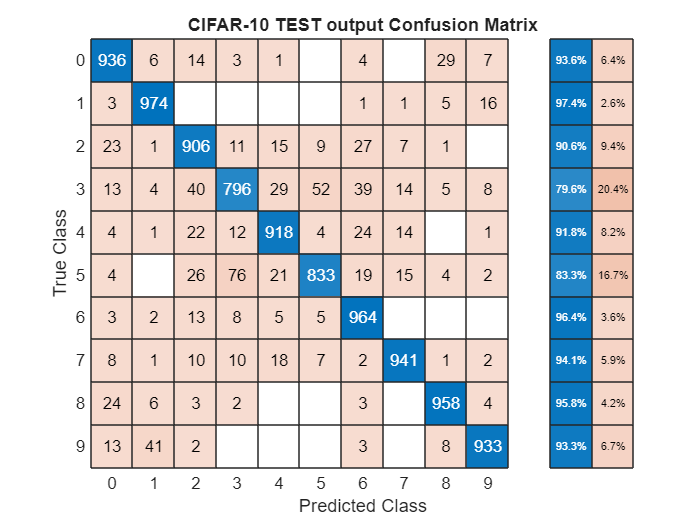

Overall Accuracy (from CM): 91.59%


trainAcc = 0.9983

valAcc = 0.9209

|   20 | Best   |     0.11782 |      2580.3 |     0.11782 |     0.11783 |      0.19892 |          286 |           12 |      0.85978 |       0.6384 |   0.00099032 |           40 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9105
                InitialLearnRate: 0.1723
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.6531
             LearnRateDropPeriod: 22
                   MiniBatchSize: 291
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.2289e-06
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 137
              ValidationPatience: 7
             ObjectiveMetricName: 


=== Running Training 21 ===



=== Done Training 21 ===


Overall Accuracy (from CM): 88.18%


trainAcc = 0.9552

valAcc = 0.8819

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |           lr |           mb |           dr |           mo |         lrdf |           l2 |           vp |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |
|================================================================================================================================================================================|
|   21 | Accept |     0.15476 |      765.84 |     0.11782 |     0.11969 |      0.17231 |          291 |           22 |      0.91046 |      0.65311 |   1.2289e-06 |            7 |


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9837
                InitialLearnRate: 0.1981
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2423
             LearnRateDropPeriod: 17
                   MiniBatchSize: 316
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0070
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 126
              ValidationPatience: 13
             ObjectiveMetricName: 'lo


=== Running Training 22 ===



=== Done Training 22 ===


Overall Accuracy (from CM): 82.81%


trainAcc = 0.8838

valAcc = 0.8428

|   22 | Accept |     0.17768 |      2697.6 |     0.11782 |      0.1243 |      0.19811 |          316 |           17 |      0.98369 |      0.24229 |    0.0070249 |           13 |


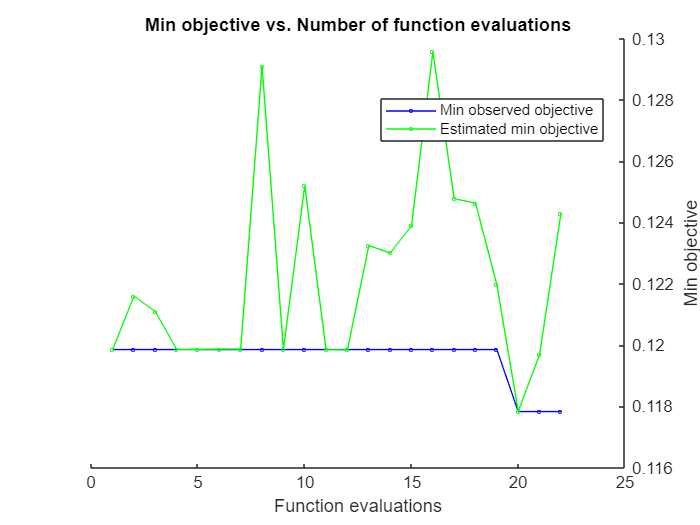

ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.8642
                InitialLearnRate: 0.1715
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5109
             LearnRateDropPeriod: 37
                   MiniBatchSize: 293
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 0.0084
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 136
              ValidationPatience: 48
             ObjectiveMetricName: 'lo


=== Running Training 23 ===


results = bayesopt(objFcn,optimVars, ...
    'MaxObjectiveEvaluations',numitr, ...
    'AcquisitionFunctionName','expected-improvement-plus',...
    'InitialX', initialPoint);

Get best hyperparameters

bestParams = results.XAtMinEstimatedObjective;

% Map parameters to variables you use in  training scripts
lr      = bestParams.lr;
mb      = bestParams.mb;
dr      = bestParams.dr;  
vf      = floor(trainDS.NumObservations/mb);    
mo      = bestParams.mo;   
lrdf    = bestParams.lrdf;
l2      = bestParams.l2;
vp      = bestParams.vp;

numRuns = 5;


Preallocate arrays

accTest = zeros(numRuns+2,1);
macroPrecisionTest = zeros(numRuns+2,1);
macroRecallTest = zeros(numRuns+2,1);
macroF1Test = zeros(numRuns+2,1);

for run = 1:numRuns
    fprintf(' Run %d \n', run);
    conv4layers;              

    createTrainingOptions("sgdm", lr, dr, 2*MaxEpochs, ...
        mb, valDS, floor(trainDS.NumObservations/mb) ,...
        mo, 1,lrdf,l2,vp);
    expNum = numitr+run;
    runfile;

    accTest(run)            = acc;
    macroPrecisionTest(run) =  macroPrecision;
    macroRecallTest(run)    = macroRecall;
    macroF1Test(run)        = macroF1;

    figure('Name',sprintf('Run %d Confusion Matrices', run),'NumberTitle','off');


     Training 

    subplot(1,3,1);
    YPredTrain = classify(net, trainDS);
    YTrain = trainLabels;
    cmTrain = confusionmat(YTrain, YPredTrain);
    confusionchart(cmTrain);
    title(sprintf('Train CM (Run %d)', run));


     Validation 

    subplot(1,3,2);  
    YPredVal = classify(net, valDS);
    YVal = valLabels;
    cmVal = confusionmat(YVal, YPredVal);
    confusionchart(cmVal);
    title(sprintf('Validation CM (Run %d)', run));


      Test 

    subplot(1,3,3);
    YPredTest = classify(net, testDS);
    YTest = testLabels;
    cmTest = confusionmat(YTest, YPredTest);
    confusionchart(cmTest);
    title(sprintf('Test CM (Run %d)', run));
end

Calculating the mean and Standard deviation

accTest(numRuns+1)            =   mean(accTest(1:numRuns));
macroPrecisionTest(numRuns+1) =   mean(macroPrecisionTest(1:numRuns));
macroRecallTest(numRuns+1)    =   mean(macroRecallTest(1:numRuns));
macroF1Test(numRuns+1)        =   mean(macroF1Test(1:numRuns));
accTest(numRuns+2)            =   std(accTest(1:numRuns));
macroPrecisionTest(numRuns+2) =   std(macroPrecisionTest(1:numRuns));
macroRecallTest(numRuns+2)    =   std(macroRecallTest(1:numRuns));
macroF1Test(numRuns+2)        =   std(macroF1Test(1:numRuns));

% Convert to percentages
accTest            = round(accTest(:) * 100, 2);
macroPrecisionTest = round(macroPrecisionTest(:) * 100, 2);
macroRecallTest    = round(macroRecallTest(:) * 100, 2);
macroF1Test        = round(macroF1Test(:) * 100, 2);

% Row names
rowNames = [arrayfun(@(x) sprintf('Run %d', x), 1:numRuns, 'UniformOutput', false), ...
            {'Mean', 'Std'}];

% Create table
resultsTable = table(accTest(:), macroPrecisionTest(:), macroRecallTest(:), macroF1Test(:), ...
    'VariableNames', {'Accuracy(%)', 'Precision(%)', 'Recall(%)', 'F1-score(%)'}, ...
    'RowNames', rowNames);

% Display the table
disp(resultsTable);


function obj = trainAndValidate(x)
    global      net options mm co MaxEpochs         ...
                trainImages valImages testImages    ...
                trainLabels valLabels testLabels    ...
                imageAugmenter trainDS valDS testDS 
    persistent expNum
    if isempty(expNum)
        expNum = 1;
    else
        expNum = expNum + 1;
    end
    vf = floor(trainDS.NumObservations/x.mb);
    createTrainingOptions("sgdm", x.lr, x.dr, 100, x.mb, valDS, vf , x.mo, 1,x.lrdf,x.l2,x.vp)
    
    conv4layers 
   
    runfile 
    
    YPredTrain = classify(net, trainDS);
    YTrain     = trainLabels;
    trainAcc = mean(YPredTrain == YTrain)

    YPredval = classify(net,valDS); 
    YVal  = valLabels;
    valAcc = mean(YPredval(:) == YVal(:))
   

   Objective: 

- maximize validation acuarrcy

- minimize validation error 

    lambda = 0.5;
    gap = trainAcc-valAcc;
    obj = (1 - valAcc) + lambda * max(gap,0);
end
